% Define initial state
% A population of 100 persons, 99 susceptible and 1 infectious
s_0 = 99;
i_0 = 1;
r_0 = 0;

% Let's interpret t to be Weeks; thus
% Infection rate: Each infected person has a chance to infect 1 susceptible
%                 person out of 50
% Recovery rate: The infection lasts 4 weeks before recovery
r_time = 2;
s_time = 12;
beta = 1 / 140;
num_week = 140;
% Run simulation
[S, I, R, W] = simulation(s_0, i_0, r_0, beta, num_week, r_time, s_time)

infected_list =     1.0000    0.7071    1.1986    1.3217    1.7241    2.0461    2.4776    2.8927    3.3231    3.6988    3.9930    4.1545    4.1589    3.9966    3.6879    3.3273    2.9063    2.5064    2.1305    1.8117    1.5469    1.3402    1.1841    1.0739    1.0029    0.9667    0.9617    0.9857    1.0372    1.1158    1.2215    1.3542    1.5136    1.6978    1.9038    2.1260    2.3562    2.5831    2.7933    2.9717    3.1040    3.1783    3.1880    3.1328    3.0193    2.8598    2.6696    2.4652    2.2611    2.0692


S =    99.0000   98.2929   97.0943   95.7726   94.0485   92.0025   89.5249   86.6322   83.3091   79.6102   75.6172   71.4627   67.3038   63.3072   60.6193   57.9991   56.2914   55.1067   54.7002   54.9346   55.8652   57.4177   59.5568   62.1817   65.1719   68.3596   71.5568   74.5677   77.2184   79.4299   81.1147   82.2669   82.8839   82.9978   82.6409   81.8551   80.6830   79.1738   77.3834   75.3784   73.2362   71.0435   68.8928   66.8758   65.0780   63.5724   62.4164   61.6490   61.2917   61.3485


I =     1.0000    1.7071    1.9057    2.5202    3.0457    3.7701    4.5236    5.3703    6.2158    7.0220    7.6918    8.1475    8.3134    8.1555    7.6845    7.0152    6.2336    5.4127    4.6370    3.9423    3.3586    2.8871    2.5243    2.2579    2.0767    1.9696    1.9285    1.9474    2.0229    2.1530    2.3373    2.5757    2.8678    3.2113    3.6016    4.0298    4.4822    4.9393    5.3764    5.7650    6.0757    6.2823    6.3663    6.3208    6.1521    5.8791    5.5294    5.1348    4.7263    4.3303


R =          0         0    1.0000    1.7071    2.9057    4.2274    5.9515    7.9975   10.4751   13.3678   16.6909   20.3898   24.3828   28.5373   31.6962   34.9856   37.4750   39.4806   40.6628   41.1232   40.7761   39.6952   37.9189   35.5603   32.7514   29.6707   26.5147   23.4849   20.7587   18.4171   16.5480   15.1574   14.2484   13.7909   13.7575   14.1151   14.8348   15.8870   17.2402   18.8566   20.6881   22.6742   24.7409   26.8035   28.7699   30.5485   32.0542   33.2162   33.9820   34.3212


W =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


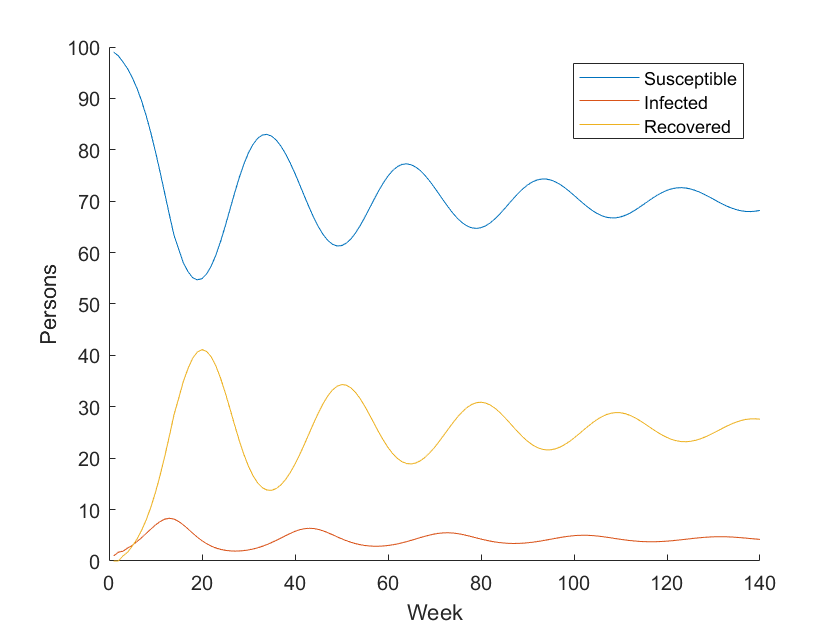


% Plot
figure(1); clf; hold on;
plot(W, S); label1 = "Susceptible";
plot(W, I); label2 = "Infected";
plot(W, R); label3 = "Recovered";

xlabel("Week")
ylabel("Persons")
legend({label1, label2, label3})

%(s, i, r, beta, r_time, s_time, infected_list, step)